clc;clear;close all;
workingPath = 'D:\deeplearning - diffraction'

workingPath = 'D:\deeplearning - diffraction'

% boundary_path = 'D:\deeplearning - diffraction\table';
CheckpointPath = '.\checkpoint'

CheckpointPath = '.\checkpoint'

gpuDevice(1);

产生数据集

pic_path ='D:\deeplearning - diffraction\diffraction\Three_write';
boundary_path = 'D:\deeplearning - diffraction\table';
diffractionDataset=Generate_train(pic_path,boundary_path);
cd(workingPath)

read picture

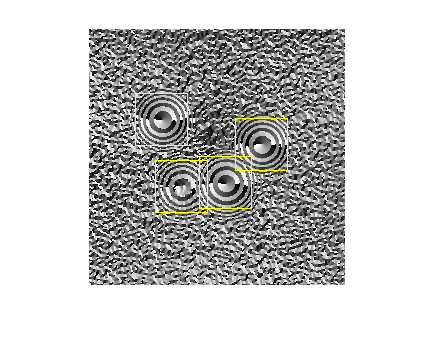

I = imread(diffractionDataset.imageFilename{40});
I = insertShape(I, 'Rectangle', diffractionDataset.boundary_cell{40});
% I = imresize(I,3);
figure
imshow(I)

分割数据集

rng(0);
shuffledIdx = randperm(height(diffractionDataset));
idx = floor(0.5 * height(diffractionDataset));
trainingData = diffractionDataset(shuffledIdx(1:idx),:);
testData = diffractionDataset(shuffledIdx(idx+1:end),:);

faster rcnn 参数

featureExtractionNetwork = resnet50;
imageSize = [256,256,3];
numClasses =1;
anchorBoxes = [
   78   78
   37   37
    53    53
   72   72
   91   91
   110   110
];
featureLayer = 'activation_40_relu';
lgraph = fasterRCNNLayers(imageSize,numClasses,anchorBoxes,featureExtractionNetwork,featureLayer);

迭代器参数

options = trainingOptions('adam', ...     %使用SGD
    'MaxEpochs', 80, ...                   %最大迭代次数
    'MiniBatchSize', 2, ...               %BatchSize
    'InitialLearnRate', 3e-4, ...         %初始学习率
    'CheckpointPath', CheckpointPath,...  %检查点
    "Verbose",true,...
    'VerboseFrequency',100,...
    "LearnRateSchedule","piecewise",...
    "LearnRateDropPeriod",40,...          %每20epoch衰减学习率
    'L2Regularization',0.0001,...
    'Shuffle','every-epoch',...
    'ExecutionEnvironment',"gpu");  %指定多GPU
%'ValidationData',testData,...



开始训练

isRetrain=0;
isfirst=1;
if (isRetrain)
    str = [CheckpointPath,'\faster_rcnn_stage_3_checkpoint__960__2019_11_11__21_26_39.mat'];
    retrain_data = load(str);
    if(isfirst)
        [detector, info] = trainFasterRCNNObjectDetector(trainingData,retrain_data.detector,options,...
            'NegativeOverlapRange', [0 0.3], ...
            'PositiveOverlapRange', [0.8 1],...
            'FreezeBatchNormalization',true);
    else
        shuffledIdx = randperm(height(testData));
        idx = floor(0.4 * height(testData));
        trainingData1 = testData(shuffledIdx(1:idx),:);
        [detector, info] = trainFasterRCNNObjectDetector(trainingData1,retrain_data.detector,options,...
            'NegativeOverlapRange', [0 0.3], ...
            'PositiveOverlapRange', [0.8 1],...
            'FreezeBatchNormalization',true);
    end  
    
else
    [detector, info] = trainFasterRCNNObjectDetector(trainingData, lgraph, options, ...
        'NegativeOverlapRange', [0 0.3], ...
        'PositiveOverlapRange', [0.8 1],...
        'FreezeBatchNormalization',true);
end

*************************************************************************
Training a Faster R-CNN Object Detector for the following object classes:

* boundary_cell

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 8).
正在初始化输入数据归一化。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　轮　　｜　　迭代　　｜　　　　经过的时间　　　　　｜　　小批量损失　　｜　　小批量准确度　　｜　　小批量　ＲＭＳＥ　　｜　　ＲＰＮ　Ｍｉｎｉ－ｂａｔｃｈ　　｜　　ＲＰＮ　Ｍｉｎｉ－ｂａｔｃｈ　　｜　　基础学习率　　｜
｜　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　｜　　　　　　　　　　｜　　　　　　　　　　　　｜　　　　　Ａｃｃｕｒａｃｙ　　　　　｜　　　　　　　ＲＭＳＥ　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　１　｜　　　　１　｜　　　　　００：００：０７　｜　　１．９９２８　｜　　　５８．２９％　｜　　　　　　　０．０９　｜　　　　　　　　　　　５０．７８％　｜　　　　　　　　　　　　　１．００　｜　　０．０００３　｜
｜　　　１　｜　　１００　｜　　　　　００：０７：２２　｜　　０．８６４７　｜　　　９９．７２％　｜　　　　　　　０．０７　｜　　　　　　　　　　　９７．２４％　｜　　　　　　　　　　　　　０．７０　｜　　０．０００３　｜
｜　　　１　｜　　２００　｜　　　　　００：１４：１９　｜　


save('D:\deeplearning - diffraction\code\factercnndetector.mat','detector')

输出结果

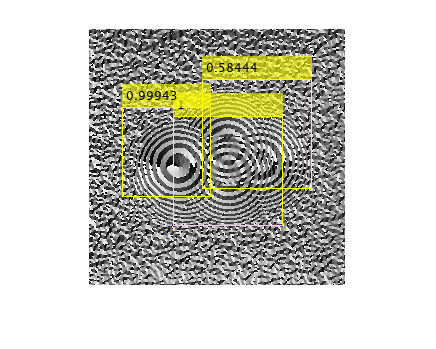

I = imread(testData.imageFilename{500});

% Run the detector.
[bboxes,scores] = detect(detector,I);

% Annotate detections in the image.
I = insertObjectAnnotation(I,'rectangle',bboxes,scores);
figure
imshow(I)

评估

numImages = height(testData);
results = table('Size',[numImages 3],...
    'VariableTypes',{'cell','cell','cell'},...
    'VariableNames',{'Boxes','Scores','Labels'});

% Run detector on each image in the test set and collect results.
for i = 1:numImages
    
    % Read the image.
    I = imread(testData.imageFilename{i});
    
    % Run the detector.
    [bboxes, scores, labels] = detect(detector, I);
    
    % Collect the results.
    % Collect the results.
    results.Boxes{i} = bboxes;
    results.Scores{i} = scores;
    results.Labels{i} = labels;
end
% Extract expected bounding box locations from test data.
expectedResults = testData(:, 2:end);

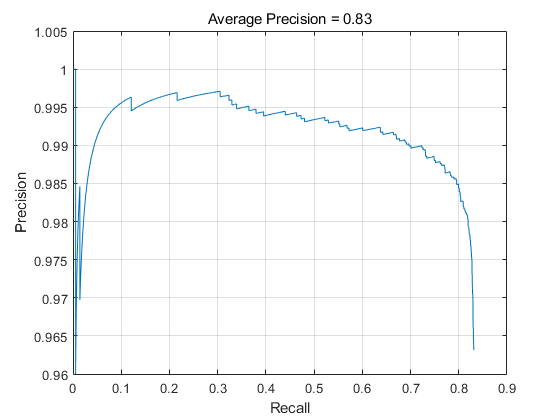


% Evaluate the object detector using Average Precision metric.
[ap, recall, precision] = evaluateDetectionPrecision(results, expectedResults);
% Plot precision/recall curve
figure
plot(recall,precision)
xlabel('Recall')
ylabel('Precision')
grid on
title(sprintf('Average Precision = %.2f', ap))

save('fastrcnn.mat','results','expectedResults','info')